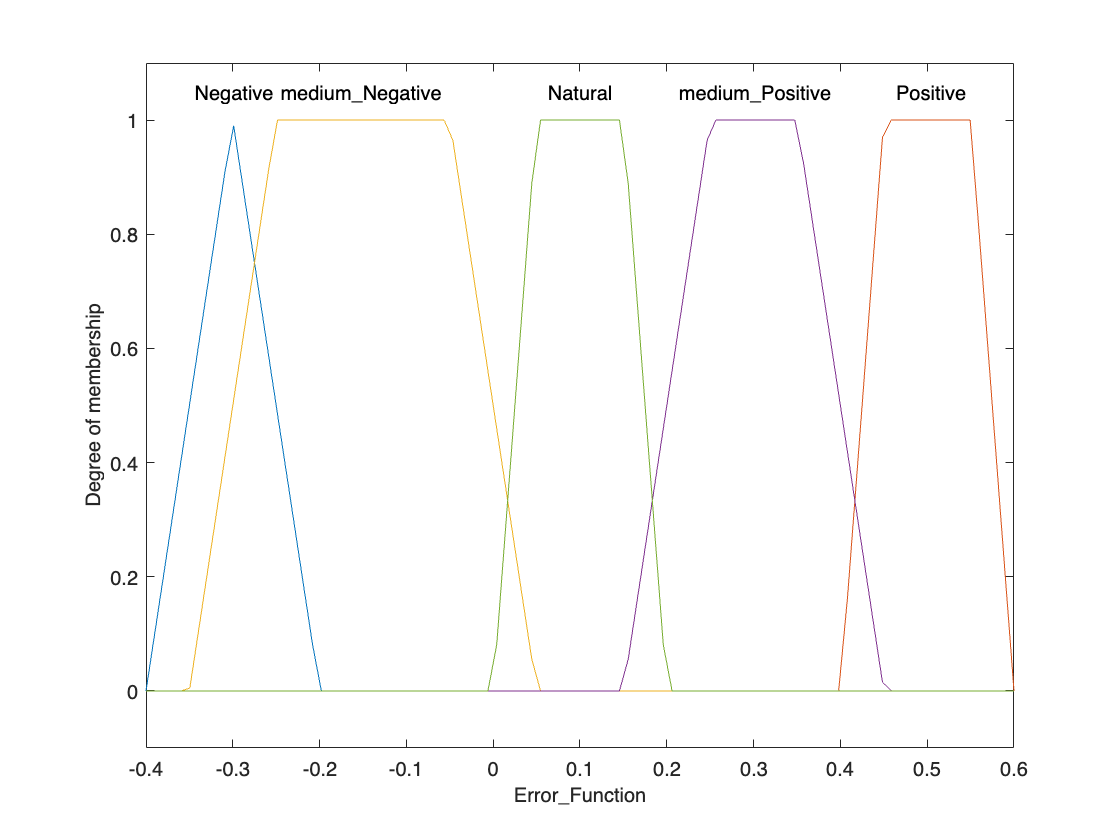

%Neurofeedback Fuzzy MISO
%% Version V1
% Authors - Mario De Los Santos, Felipe Orihuela-Espina,
% Javier Herrara-Vega, Gustavo Rodriguez, Javier Andreu-Perez
% Date - July 12st, 2022
% Email - madlsh3517@gmail.com

cFNIRS_MISO = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 25, ...
    'AddRule', 'none');

cFNIRS_MISO.Inputs(1).Name = 'Error_Function';
cFNIRS_MISO.Inputs(1).Range = [-0.4, 0.6]; 
%Membership function shapes
cFNIRS_MISO.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cFNIRS_MISO.Inputs(1).MembershipFunctions(1).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(1).MembershipFunctions(1).Parameters = [-0.4 -0.3 -0.3 -0.2];

cFNIRS_MISO.Inputs(1).MembershipFunctions(3).Name = 'medium_Negative';
cFNIRS_MISO.Inputs(1).MembershipFunctions(3).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(1).MembershipFunctions(3).Parameters = [-0.35 -0.25 -0.05 0.05];

cFNIRS_MISO.Inputs(1).MembershipFunctions(5).Name = 'Natural';
cFNIRS_MISO.Inputs(1).MembershipFunctions(5).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(1).MembershipFunctions(5).Parameters = [0 0.05 0.15 0.2];

cFNIRS_MISO.Inputs(1).MembershipFunctions(4).Name = 'medium_Positive';
cFNIRS_MISO.Inputs(1).MembershipFunctions(4).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(1).MembershipFunctions(4).Parameters = [0.15 0.25 0.35 0.45];

cFNIRS_MISO.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cFNIRS_MISO.Inputs(1).MembershipFunctions(2).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(1).MembershipFunctions(2).Parameters = [0.4 0.45 0.55 0.6];

plotmf(cFNIRS_MISO, 'input', 1, 100);

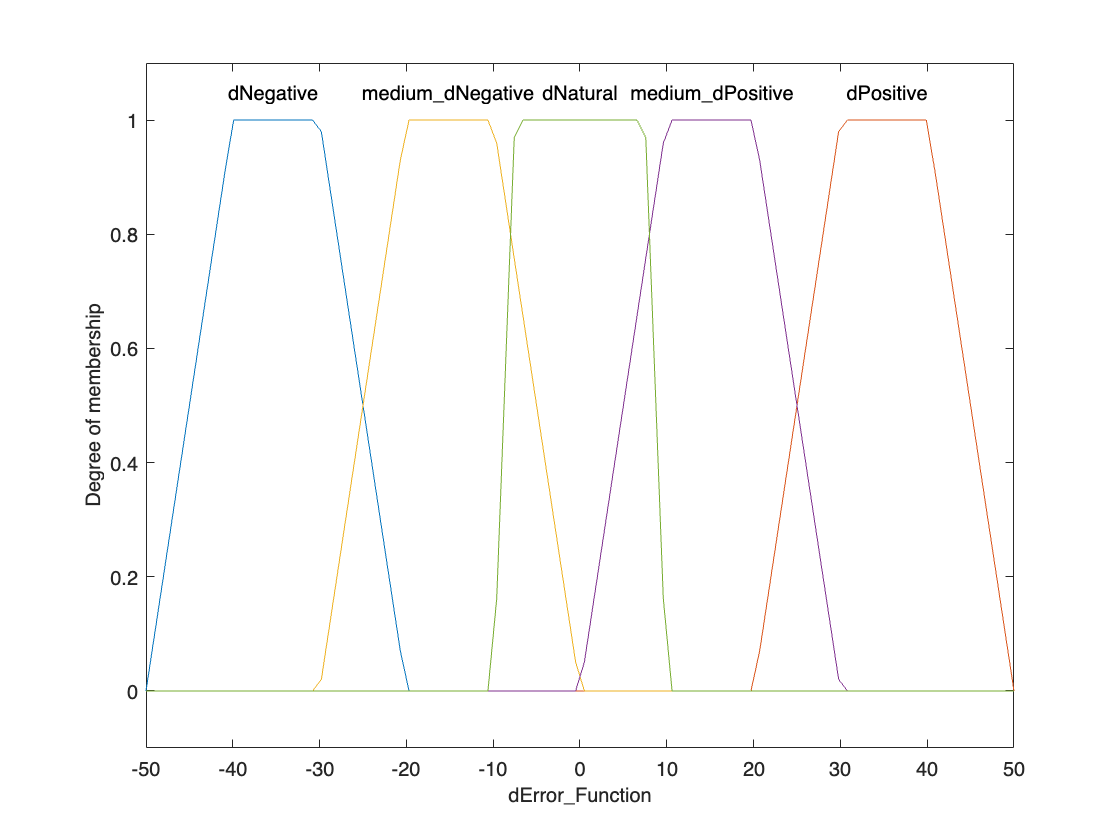


cFNIRS_MISO.Inputs(2).Name = 'dError_Function';
cFNIRS_MISO.Inputs(2).Range = [-50, 50]; 

%Membership function shapes
cFNIRS_MISO.Inputs(2).MembershipFunctions(1).Name = 'dNegative';
cFNIRS_MISO.Inputs(2).MembershipFunctions(1).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(2).MembershipFunctions(1).Parameters = [-50 -40 -30 -20];

cFNIRS_MISO.Inputs(2).MembershipFunctions(3).Name = 'medium_dNegative';
cFNIRS_MISO.Inputs(2).MembershipFunctions(3).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(2).MembershipFunctions(3).Parameters = [-30 -20 -10 0];

cFNIRS_MISO.Inputs(2).MembershipFunctions(5).Name = 'dNatural';
cFNIRS_MISO.Inputs(2).MembershipFunctions(5).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(2).MembershipFunctions(5).Parameters = [-10 -7.5 7.5 10];

cFNIRS_MISO.Inputs(2).MembershipFunctions(4).Name = 'medium_dPositive';
cFNIRS_MISO.Inputs(2).MembershipFunctions(4).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(2).MembershipFunctions(4).Parameters = [0 10 20 30];

cFNIRS_MISO.Inputs(2).MembershipFunctions(2).Name = 'dPositive';
cFNIRS_MISO.Inputs(2).MembershipFunctions(2).Type ='trapmf'; %Trampf-shaped memebership function
cFNIRS_MISO.Inputs(2).MembershipFunctions(2).Parameters = [20 30 40 50];

plotmf(cFNIRS_MISO, 'input', 2, 100);

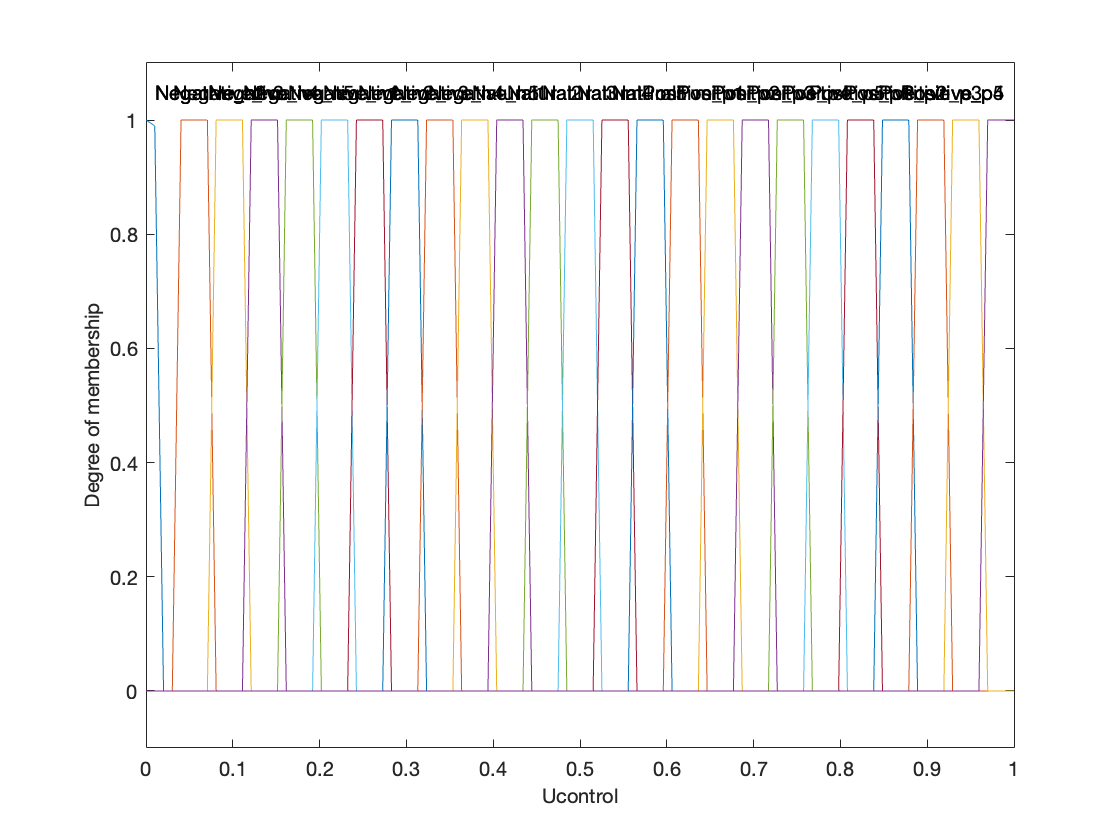

%OUTPUTS
cFNIRS_MISO.Outputs(1).Name = 'Ucontrol';
cFNIRS_MISO.Outputs(1).Range = [0,1];

%Negatives
cFNIRS_MISO.Outputs(1).MembershipFunctions(1).Name = 'Negative_n1'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(1).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(1).Parameters = [0,0,0.01,0.02];

cFNIRS_MISO.Outputs(1).MembershipFunctions(2).Name = 'Negative_n2'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(2).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(2).Parameters = [0.04,0.04,0.08,0.08];

cFNIRS_MISO.Outputs(1).MembershipFunctions(3).Name = 'Negative_n3'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(3).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(3).Parameters = [0.08, 0.08,0.12,0.12];

cFNIRS_MISO.Outputs(1).MembershipFunctions(4).Name = 'Negative_n4'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(4).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(4).Parameters = [0.12,0.12,0.16,0.16];

cFNIRS_MISO.Outputs(1).MembershipFunctions(5).Name = 'Negative_n5'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(5).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(5).Parameters = [0.16,0.16,0.2,0.2];


%Medium Negatives
cFNIRS_MISO.Outputs(1).MembershipFunctions(6).Name = 'mNegative_n1'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(6).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(6).Parameters = [0.2,0.2,0.24,0.24];

cFNIRS_MISO.Outputs(1).MembershipFunctions(7).Name = 'mNegative_n2'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(7).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(7).Parameters = [0.24,0.24,0.28,0.28];

cFNIRS_MISO.Outputs(1).MembershipFunctions(8).Name = 'mNegative_n3'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(8).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(8).Parameters = [0.28, 0.28,0.32,0.32];

cFNIRS_MISO.Outputs(1).MembershipFunctions(9).Name = 'mNegative_n4'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(9).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(9).Parameters = [0.32,0.32,0.36,0.36];

cFNIRS_MISO.Outputs(1).MembershipFunctions(10).Name = 'mNegative_n5'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(10).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(10).Parameters = [0.36,0.36,0.4,0.4];


%Naturals
cFNIRS_MISO.Outputs(1).MembershipFunctions(11).Name = 'Natural1'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(11).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(11).Parameters = [0.4,0.4,0.44,0.44];

cFNIRS_MISO.Outputs(1).MembershipFunctions(12).Name = 'Natural2'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(12).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(12).Parameters = [0.44,0.44,0.48,0.48];

cFNIRS_MISO.Outputs(1).MembershipFunctions(13).Name = 'Natural3'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(13).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(13).Parameters = [0.48, 0.48,0.52,0.52];

cFNIRS_MISO.Outputs(1).MembershipFunctions(14).Name = 'Natural4'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(14).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(14).Parameters = [0.52,0.52,0.56,0.56];

cFNIRS_MISO.Outputs(1).MembershipFunctions(15).Name = 'Natural5'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(15).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(15).Parameters = [0.56,0.56,0.6,0.6];

%Medium Positive
cFNIRS_MISO.Outputs(1).MembershipFunctions(16).Name = 'mPositive_p1'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(16).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(16).Parameters = [0.6,0.6,0.64,0.64];

cFNIRS_MISO.Outputs(1).MembershipFunctions(17).Name = 'mPositive_p2'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(17).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(17).Parameters = [0.64,0.64,0.68,0.68];

cFNIRS_MISO.Outputs(1).MembershipFunctions(18).Name = 'mPositive_p3'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(18).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(18).Parameters = [0.68, 0.68,0.72,0.72];

cFNIRS_MISO.Outputs(1).MembershipFunctions(19).Name = 'mPositive_p4'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(19).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(19).Parameters = [0.72,0.72,0.76,0.76];

cFNIRS_MISO.Outputs(1).MembershipFunctions(20).Name = 'mPositive_p5'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(20).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(20).Parameters = [0.76,0.76,0.8,0.8];


%Positive
cFNIRS_MISO.Outputs(1).MembershipFunctions(21).Name = 'Positive_p1'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(21).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(21).Parameters = [0.8,0.8,0.84,0.84];

cFNIRS_MISO.Outputs(1).MembershipFunctions(22).Name = 'Positive_p2'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(22).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(22).Parameters = [0.84,0.84,0.88,0.88];

cFNIRS_MISO.Outputs(1).MembershipFunctions(23).Name = 'Positive_p3'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(23).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(23).Parameters = [0.88, 0.88,0.92,0.92];

cFNIRS_MISO.Outputs(1).MembershipFunctions(24).Name = 'Positive_p4'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(24).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(24).Parameters = [0.92,0.92,0.96,0.96];

cFNIRS_MISO.Outputs(1).MembershipFunctions(25).Name = 'Positive_p5'; %Negative Low alternative
cFNIRS_MISO.Outputs(1).MembershipFunctions(25).Type = 'trapmf'; 
cFNIRS_MISO.Outputs(1).MembershipFunctions(25).Parameters = [0.96,0.96,1,1];


plotmf(cFNIRS_MISO, 'output', 1, 100);

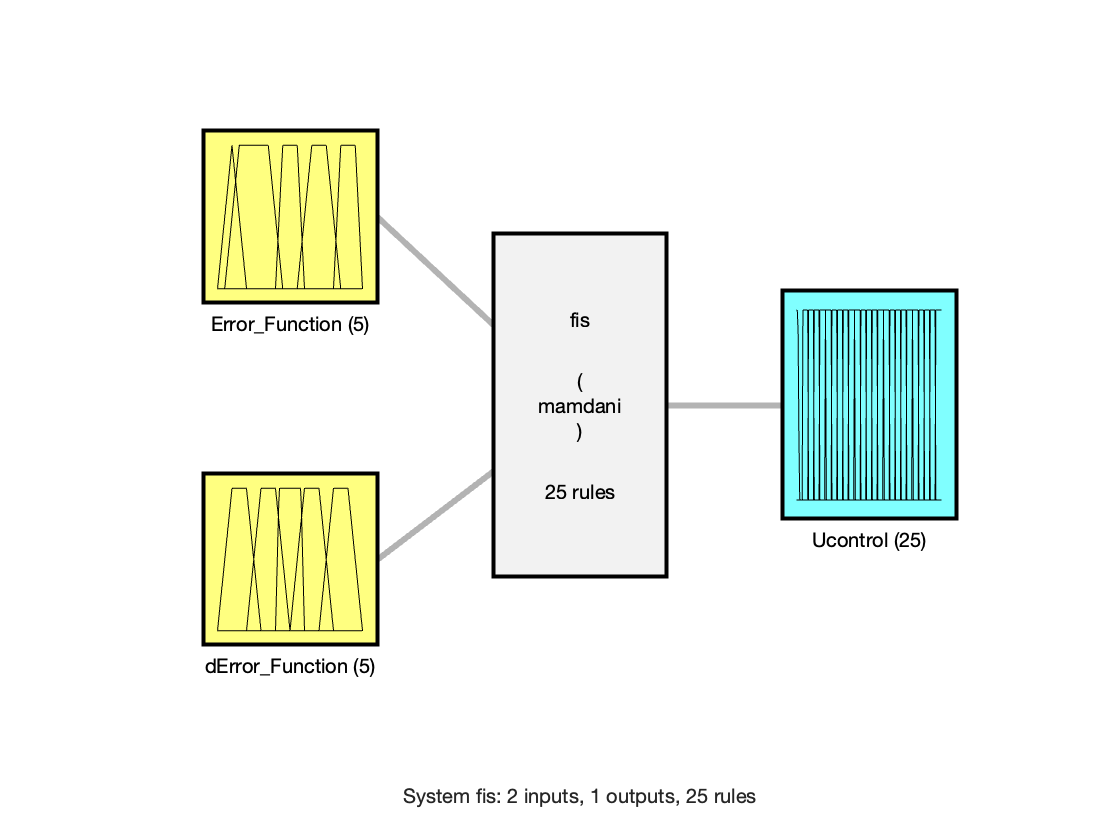

%Rules
rules = ["If Error_Function is Negative and dError_Function is dNegative then Ucontrol is Negative_n1";...
    "If Error_Function is Negative and dError_Function is medium_dNegative then Ucontrol is mNegative_n1";...
    "If Error_Function is Negative and dError_Function is dNatural then Ucontrol is Natural1";...
    "If Error_Function is Negative and dError_Function is medium_dPositive then Ucontrol is mPositive_p1";...
    "If Error_Function is Negative and dError_Function is dPositive then Ucontrol is Positive_p1";...
    
    "If Error_Function is medium_Negative and dError_Function is dNegative then Ucontrol is Negative_n2";...
    "If Error_Function is medium_Negative and dError_Function is medium_dNegative then Ucontrol is mNegative_n2";...
    "If Error_Function is medium_Negative and dError_Function is dNatural then Ucontrol is Natural2";...
    "If Error_Function is medium_Negative and dError_Function is medium_dPositive then Ucontrol is mPositive_p2";...
    "If Error_Function is medium_Negative and dError_Function is dPositive then Ucontrol is Positive_p2";...

    "If Error_Function is Natural and dError_Function is dNegative then Ucontrol is  Negative_n3";...
    "If Error_Function is Natural and dError_Function is medium_dNegative then Ucontrol mNegative_n3";...
    "If Error_Function is Natural and dError_Function is dNatural then Ucontrol is Natural3";...
    "If Error_Function is Natural and dError_Function is medium_dPositive then Ucontrol is mPositive_p3";...
    "If Error_Function is Natural and dError_Function is dPositive then Ucontrol is Positive_p3";...

    "If Error_Function is medium_Positive and dError_Function is dNegative then Ucontrol is Negative_n4";...
    "If Error_Function is medium_Positive and dError_Function is medium_dNegative then Ucontrol is mNegative_n4";...
    "If Error_Function is medium_Positive and dError_Function is dNatural then Ucontrol is Natural4";...
    "If Error_Function is medium_Positive and dError_Function is medium_dPositive then Ucontrol is mPositive_p4";...
    "If Error_Function is medium_Positive and dError_Function is dPositive then Ucontrol is Positive_p4";...

    "If Error_Function is Positive and dError_Function is dNegative then Ucontrol is Negative_n5";...
    "If Error_Function is Positive and dError_Function is medium_dNegative then Ucontrol is mNegative_n5";...
    "If Error_Function is Positive and dError_Function is dNatural then Ucontrol is Natural5";...
    "If Error_Function is Positive and dError_Function is medium_dPositive then Ucontrol is mPositive_p5";...
    "If Error_Function is Positive and dError_Function is dPositive then Ucontrol is Positive_p5"];

cFNIRS_MISO = addRule(cFNIRS_MISO,rules);
figure
plotfis(cFNIRS_MISO)

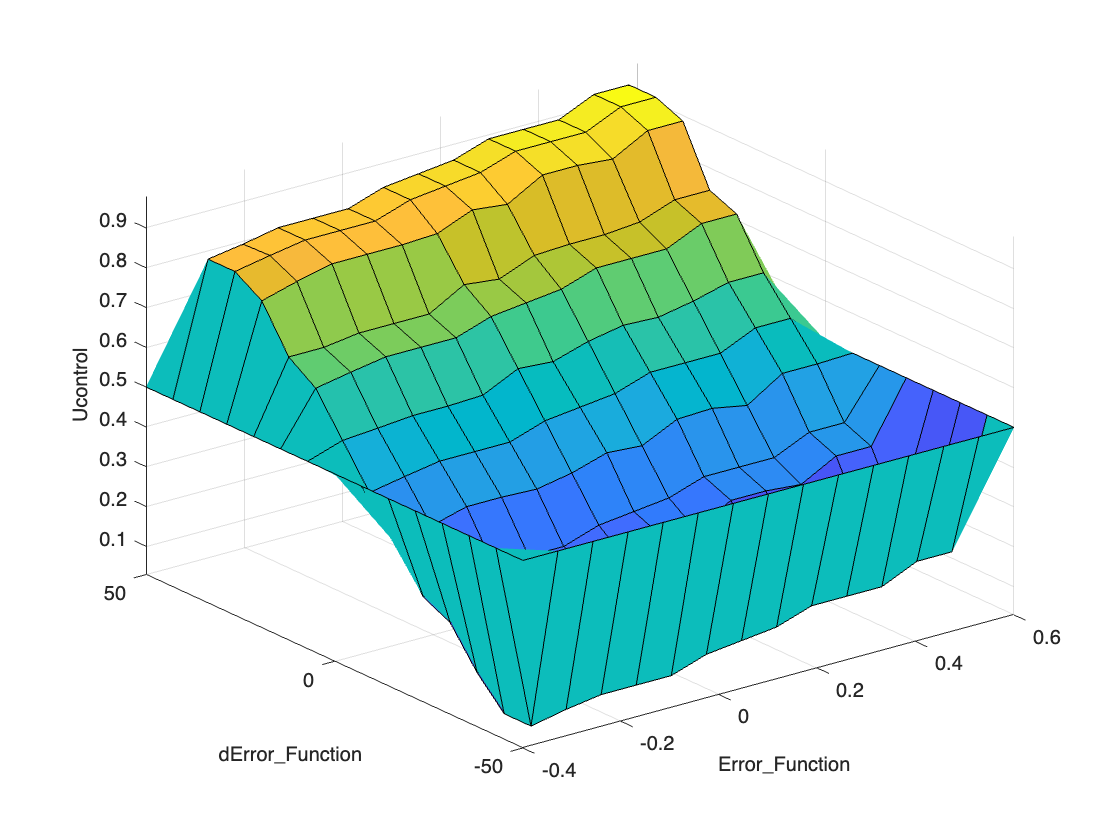

gensurf(cFNIRS_MISO)

%fuzzyLogicDesigner(cFNIRS_MISO)